clear 
clc
close all

# Create Simple Deep Learning Network for Classification

This example shows how to create and train a simple convolutional neural network for deep learning classification. Convolutional neural networks are essential tools for deep learning, and are especially suited for image recognition. Learn how to set up network layers, image data, and training options, train the network, and test the classification accuracy.

## Load and Explore the Image Data

Load the digit sample data as an `ImageDatastore` object.

digitDatasetPath = fullfile(matlabroot,'toolbox','nnet','nndemos', ...
        'nndatasets','DigitDataset');
digitData = imageDatastore(digitDatasetPath, ...
        'IncludeSubfolders',true,'LabelSource','foldernames');

`imageDatastore` function labels the images automatically based on folder names and stores the data as an `ImageDatastore` object. An `ImageDatastore` object lets you store large image data, including data that do not fit in memory, and efficiently read batches of images during training of a convolutional neural network.

Display some of the images in the datastore. 

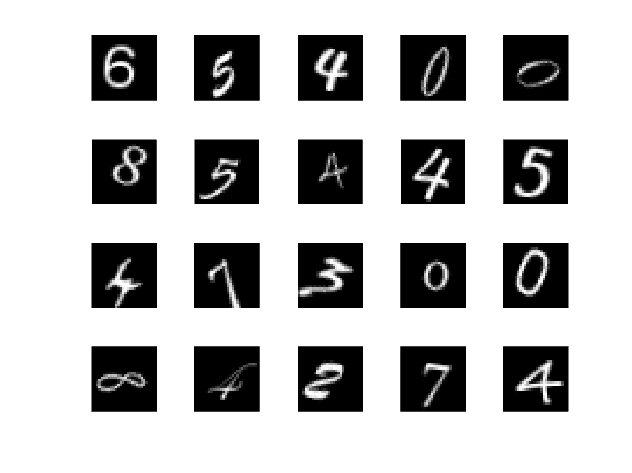

figure;
perm = randperm(10000,20);
for i = 1:20
    subplot(4,5,i);
    imshow(digitData.Files{perm(i)});
end

figure;

Check the number of images in each category. 

CountLabel = digitData.countEachLabel;

`CountLabel` is a table that contains the labels and the number of images in each label. It shows that the datastore contains 1000 images for each of the digits 0-9, a total of 10000. Hence, there are 10 classes. You can specify the number of classes in the last fully connected layer of your network as the `OutputSize` parameter. The images are generated by applying random transformations to digit images created using different fonts.

You must specify the size of the images in the input layer of the network. Check the size of the first image in `digitData` .

img = readimage(digitData,1);
size(img)

ans =     28    28


Each digit image is 28-by-28-by-1 pixels.

## Specify Training and Test Sets

Divide the data into training and test sets, so that each category in the training set has 750 images and the test set has the remaining images from each label.

trainingNumFiles = 750;
rng(1) % For reproducibility
[trainDigitData,testDigitData] = splitEachLabel(digitData, ...
				trainingNumFiles,'randomize');

`splitEachLabel` splits the image files in `digitData` into two new datastores, `trainDigitData` and `testDigitData`. 

## Define the Network Layers

Define the convolutional neural network architecture. layers = [imageInputLayer([28 28 1]) convolution2dLayer(5,20) reluLayer maxPooling2dLayer(2,'Stride',2) fullyConnectedLayer(10) softmaxLayer classificationLayer()]; %+-3min

layers = [imageInputLayer([28 28 1])
  convolution2dLayer(5,24)
  reluLayer
  
  maxPooling2dLayer(2,'Stride',2)
  
%   convolution2dLayer(5,24)
%   reluLayer  
%   
  fullyConnectedLayer(10)
  softmaxLayer
  classificationLayer()]; %+-10min

% layers = [imageInputLayer([28 28 1])
%           convolution2dLayer(5,20)
%           reluLayer
%           %maxPooling2dLayer(2,'Stride',2)
%           convolution2dLayer(5,24)
%           reluLayer 
%           maxPooling2dLayer(2,'Stride',2)
%           convolution2dLayer(3,36)
%           reluLayer 
%           fullyConnectedLayer(10)
%           softmaxLayer
%           classificationLayer()];  %+-3min
      
% layers = [imageInputLayer([28 28 1])
%           convolution2dLayer(5,30)
%           reluLayer
%           maxPooling2dLayer(2,'Stride',2)
%           fullyConnectedLayer(512)
%           fullyConnectedLayer(10)
%           softmaxLayer
%           classificationLayer()];  %+-3min

**Image Input Layer** An [imageInputLayer](docid:nnet_ref.bu4mb_9) is where you specify the image size, which, in this case, is 28-by-28-by-1. These numbers correspond to the height, width, and the channel size. The digit data consists of gray scale images, hence the channel size (color channel) is 1. For a color image, the channel size would be 3, corresponding to the RGB values. You can also specify any data transformation at this layer, such as data normalization or data augmentation (randomly flip or crop the data). These are usually used to avoid overfitting. You do not need to shuffle the data as `trainNetwork` automatically does it at the beginning of the training.

**Convolutional Layer** In the convolutional layer, the first argument is `filterSize`, which is the height and width of the filters the training function uses while scanning along the images. In this example, the number 5 indicates that the filter size is [5,5]. You can also specify different sizes for the height and the width of the filter. The second argument is the number of filters, which is the number of neurons that connect to the same region of the output. This parameter determines the number of the feature maps. You can also define the `Stride` or learning rates for this layer in the call to [convolution2dLayer](docid:nnet_ref.bu4i26l).

**ReLU Layer** The convolutional layer is followed by a nonlinear activation function. MATLAB uses the rectified linear unit function, specified by  [reluLayer](docid:nnet_ref.bu4mbw1).

**Max-Pooling Layer** The convolutional layer (with the activation function) is usually followed by a down-sampling operation to reduce the number of parameters and as another way of avoiding overfitting. One way of down-sampling is max-pooling, which is specified by the [maxPoolingLayer](docid:nnet_ref.bu5lhn5) function. This layer returns the maximum values of rectangular regions of inputs, specified by the first argument, `poolSize`. In this example, the size of the rectangular region is [2,2]. The optional argument `Stride` determines the step size the training function takes as it scans along the image. This max-pooling layer takes place between the convolutional layers when there are multiple of them in the network.

**Fully Connected Layer** The convolutional (and down-sampling) layers are followed by one or more fully connected layers. As the name suggests, all neurons in a fully connected layer connect to the neurons in the layer previous to it. This layer combines all of the features (local information) learned by the previous layers across the image to identify the larger patterns. The last fully connected layer combines them to classify the images. That is why, the OutputSize parameter in the last fully connected layer is equal to the number of classes in the target data. In this example the output size is 10, corresponding to the 10 digits. 

**Softmax Layer** The fully connected layer usually uses the softmax activation function for classification. You can add the softmax layer by using the [softmaxLayer](docid:nnet_ref.bu5lhgb) function after the last fully connected layer.

**Classification Layer** The final layer is the classification layer, defined by using the [classificationLayer](docid:nnet_ref.bu5lho8) function. This layer uses the probabilities returned by the softmax activation function for each input to assign it to one of the mutually exclusive classes.

## Specify the Training Options

After defining the layers (network structure), specify the training options. Set the options to default settings for the stochastic gradient descent with momentum. Set the maximum number of epochs at 15 (an epoch is a full training cycle on the whole training data), and start the training with an initial learning rate of 0.0001.

options = trainingOptions('sgdm','MaxEpochs',15, ...
    'MiniBatchSize', 128, ...
	'InitialLearnRate',0.0001,'OutputFcn',@plotTrainingAccuracy);  
    %Default MiniBatchSize is 128.

## Train the Network Using Training Data

Train the network you defined in layers, using the training data and the training options you defined in the previous steps.

在单 CPU 上训练。
正在初始化输入数据归一化。
｜＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝｜
｜　　轮　　｜　　迭代　　｜　　　　经过的时间　　　　　｜　　小批量准确度　　｜　　小批量损失　　｜　　基础学习率　　｜
｜　　　　　｜　　　　　　｜　　（ｈｈ：ｍｍ：ｓｓ）　　｜　　　　　　　　　　｜　　　　　　　　　｜　　　　　　　　　｜
｜＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝｜
｜　　　１　｜　　　　１　｜　　　　　００：００：００　｜　　　　３．１２％　｜　４２．７８１８　｜　１．００００ｅ－０４　｜
｜　　　１　｜　　　５０　｜　　　　　００：００：０３　｜　　　４０．６２％　｜　　４．５２７７　｜　１．００００ｅ－０４　｜
｜　　　１　｜　　１００　｜　　　　　００：００：０４　｜　　　７５．００％　｜　　１．３８１４　｜　１．００００ｅ－０４　｜
｜　　　１　｜　　１５０　｜　　　　　００：００：０５　｜　　　６２．５０％　｜　　１．０４２５　｜　１．００００ｅ－０４　｜
｜　　　１　｜　　２００　｜　　　　　００：００：０７　｜　　　７８．１２％　｜　　１．２５１６　｜　１．００００ｅ－０４　｜
｜　　　２　｜　　２５０　｜　　　　　００：００：０８　｜　　　８１．２５％　｜　　０．６４６２　｜　１．００００ｅ－０４　｜
｜　　　２　｜　　３００　｜　　　　　００：００：０９　｜　　　８１．２５％　｜　　０．９０６１　｜　１．００００ｅ－０４　｜
｜　　　２　｜　　３５０　｜　　　　　００：００：１０　｜　　　７８．１２％　｜　　０．５９０１　｜　１．００００ｅ－０４　｜
｜　　　２　｜　　４００　｜　　　　　００：００：１２　｜　　　９３．７５％　｜　　０．１８３６　｜　１．００００ｅ－０４　｜
｜　　　２　｜　　４５０　｜　　　　　００：００：１３　｜　　　９０．６２％　｜　　０．１３６４　｜　１．００００ｅ－０４　｜
｜　　　３　｜　　５００　｜　　　　　００：００：１４　｜　　　９０．６２％　｜　　０．４５９５　｜　１．００００ｅ－０４　｜
｜　　　３　｜　　５５０　｜　　　　　００：００：１

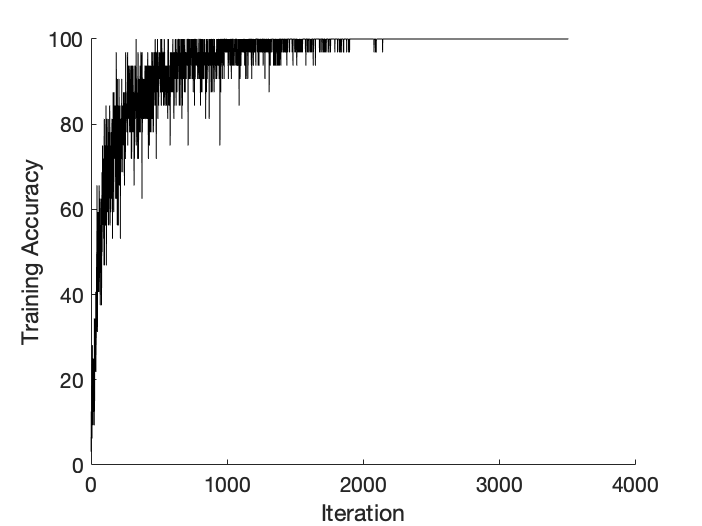

｜　　１５　｜　３５１０　｜　　　　　００：０１：３３　｜　　１００．００％　｜　　０．０００６　｜　１．００００ｅ－０４　｜
｜＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝｜
训练结束: 已完成最大轮数。


tic
convnet = trainNetwork(trainDigitData,layers,options);

toc

历时 95.713378 秒。


`trainNetwork` displays the hardware it uses for training in the display window. It uses a GPU by default if there is one available (requires Parallel Computing Toolbox (TM) and a CUDA-enabled GPU with compute capability 3.0 and higher). If there is no available GPU, it uses a CPU. You can also specify the execution environment using the `'ExecutionEnvironment'` name-value pair argument in the call to `trainingOptions`.

The progress window shows the mini-batch loss and the mini-batch accuracy for the first iteration, last iteration and every 50 iterations in between. The mini-batch loss is the [cross-entropy loss](docid:nnet_ref.bu80p30-3) and the mini-batch accuracy is the percentage of images in the current mini-batch that the network being trained correctly classifies.

It also shows the cumulative time it takes for training and the learning rate at that iteration. In this example, the base learning rate is fixed at 0.0001 through the entire training process. You can also adjust this and reduce the learning rate at certain number of epochs. For more details, see the `trainingOptions` function reference page.

## Classify the Images in the Test Data and Compute Accuracy

Run the trained network on the test set that was not used to train the network and predict the image labels (digits).

YTest = classify(convnet,testDigitData);
TTest = testDigitData.Labels;

Calculate the accuracy. 

testAccuracy = sum(YTest == TTest)/numel(TTest)

testAccuracy = 0.9856

Accuracy is the ratio of the number of true labels in the test data matching the classifications from classify, to the number of images in the test data. In this case about 98% of the digit estimations match the true digit values in the test set.

convnet.Layers()

无法解析名称 'convnet.Layers'。

%Visualize the CNNs
layer = 2;
name = convnet.Layers(layer).Name;
channels = 1:convnet.Layers(layer).NumFilters;
I = deepDreamImage(convnet,layer,channels,'PyramidLevels',5);

｜＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝｜
｜　　迭代　　｜　　激活强度　　｜　　金字塔层级　　｜
｜＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝｜
｜　　　　１　｜　　　０．０６　｜　　　　　　　１　｜
｜　　　　２　｜　　　１．７０　｜　　　　　　　１　｜
｜　　　　３　｜　　　３．３５　｜　　　　　　　１　｜
｜　　　　４　｜　　　５．００　｜　　　　　　　１　｜
｜　　　　５　｜　　　６．６４　｜　　　　　　　１　｜
｜　　　　６　｜　　　８．２９　｜　　　　　　　１　｜
｜　　　　７　｜　　　９．９４　｜　　　　　　　１　｜
｜　　　　８　｜　　１１．５９　｜　　　　　　　１　｜
｜　　　　９　｜　　１３．２３　｜　　　　　　　１　｜
｜　　　１０　｜　　１４．８８　｜　　　　　　　１　｜
｜　　　　１　｜　　　４．９７　｜　　　　　　　２　｜
｜　　　　２　｜　　　５．７１　｜　　　　　　　２　｜
｜　　　　３　｜　　　６．４６　｜　　　　　　　２　｜
｜　　　　４　｜　　　７．２１　｜　　　　　　　２　｜
｜　　　　５　｜　　　７．９６　｜　　　　　　　２　｜
｜　　　　６　｜　　　８．７１　｜　　　　　　　２　｜
｜　　　　７　｜　　　９．４６　｜　　　　　　　２　｜
｜　　　　８　｜　　１０．２１　｜　　　　　　　２　｜
｜　　　　９　｜　　１０．９６　｜　　　　　　　２　｜
｜　　　１０　｜　　１１．７１　｜　　　　　　　２　｜
｜　　　　１　｜　　　７．６０　｜　　　　　　　３　｜
｜　　　　２　｜　　　７．６３　｜　　　　　　　３　｜
｜　　　　３　｜　　　７．６６　｜　　　　　　　３　｜
｜　　　　４　｜　　　７．６８　｜　　　　　　　３　｜
｜　　　　５　｜　　　７．７１　｜　　　　　　　３　｜
｜　　　　６　｜　　　７．７４　｜　　　　　　　３　｜
｜　　　　７　｜　　　７．７７　｜　　　　　　　３　｜
｜　　　　８　｜　　　７．８０　｜　　　　　　　３　｜
｜　　　　９　｜　　　７．８２　｜　　　　　　　３　｜
｜　　　１０　｜　　　７．８５　｜　　　　　　　３　｜
｜　　　　１　｜　　　３．７１　｜　　　　　　　４　｜
｜　　　　２　｜　　　３．５２　｜　　　　　　　４　｜
｜　　　　３　｜　　　３．３３　｜　　　

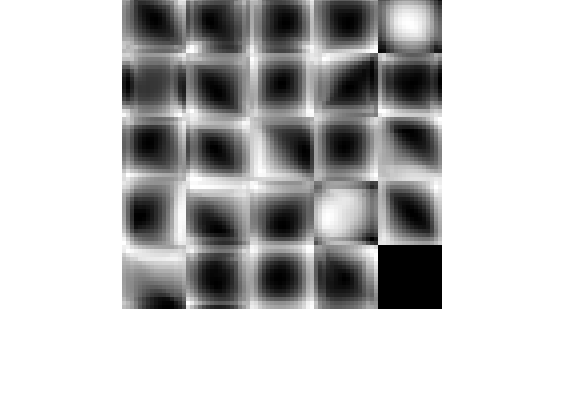

figure;
I = imtile(I,'ThumbnailSize',[64 64]);
imshow(I);
title(['Layer ',name,' Features']);


layer = 5;
name = convnet.Layers(layer).Name;
channels = 1:convnet.Layers(layer).NumFilters;

未识别类 'nnet.cnn.layer.FullyConnectedLayer' 的方法、属性或字段 'NumFilters'。

I = deepDreamImage(convnet,layer,channels,'PyramidLevels',5);
figure;
I = imtile(I,'ThumbnailSize',[64 64]);
imshow(I);
title(['Layer ',name,' Features']);

%Visualize fully connected layer
layer = 7;
channels=1:10;
I = deepDreamImage(convnet,layer,channels, ...
        'Verbose',false, ...
        'NumIterations',100);
    
figure;
I = imtile(I,'ThumbnailSize',[128 128]);
imshow(I);
name = convnet.Layers(layer).Name;
title(['Layer ',name,' Features']);


function plotTrainingAccuracy(info)

persistent plotObj

if info.State == "start"
    plotObj = animatedline;
    xlabel("Iteration")
    ylabel("Training Accuracy")
elseif info.State == "iteration"
    addpoints(plotObj,info.Iteration,info.TrainingAccuracy)
    drawnow limitrate nocallbacks
end

end